# Linear Control Design II - Group Work Problem Module 16

## **Part A - **Time Dependent Discrete LQR Control: first order system.

The purpose of this exercise is to illustrate in detail what how a time dependent optimal controller is designed for a simple first order system. Consider a discrete time controller for a system given by:


$$x(k+1)=0.3679 \: x(k) + 0.6321 \: u(k)$$


with the boundary condition that $x(0)=1$. For this system find an optimal controller to minimizes the performance index:


$$J = \frac{1}{2}\left[ x(10)^2 \right] + \frac{1}{2} \sum\limits_{k=0}^{9}\left[ x^2(k) + u^2(k) \right]$$


Note that in this example the weighting matrices have been selected to be:


$$\mathbf{S}=1 \qquad \mathbf{R_1}=1 \qquad \mathbf{R_2}=1$$


The minimum value of the index $J$ is also to be determined.

To solve this problem it is required that it be solved backwards from the final time. The boundary condition on the matrix $\mathbf{P}(N)$is:


$$\mathbf{P}(N) = \mathbf{S} \Rightarrow \mathbf{P}(N) = \mathbf{P}(10)=\mathbf{S}=1$$


The Riccati equation has to be solved in order to calculate the time varying optimal gain. In this case it can be written as:


$$\mathbf{P}(k) = 1+0.3679 \cdot \mathbf{P}(k+1)\left[ 1+0.6321 \cdot 1 \cdot 0.6321 \cdot \mathbf{P}(k+1) \right]^{-1}0.3679$$


which can be simplified to:


$$\mathbf{P}(k) = 1+0.1354 \cdot \mathbf{P}(k+1)\left[ 1+0.3996 \cdot \mathbf{P}(k+1) \right]^{-1}$$


One can now calculate backwards to the desired start time:

 
$$\mathbf{P}(9) = 1+0.1354 \cdot 1 \cdot \left[ 1+0.3996\cdot 1 \right]^{-1} = 1.0967\\ \mathbf{P}(8) = \ldots$$


**Problem 1 **Write a Matlab program to carry though these calculations to find $\mathbf{P}(0)$. What is especially noticeable about the values of $\mathbf{P}(k)$ during this process? What is the steady state value of $\mathbf{P}(k)$ i.e. $\mathbf{P}_{SS}$? Note that this value must be positive as $\mathbf{P}(k)$must be positive definite.

Calculate now the feedback gains necessary (at the different sampling times) to accomplish the desired control.

**Solution:**

% Your solution goes here:




**Problem 2 **The optimal control law is:


$$u(k) = -\mathbf{K}(k)x(k)$$


Use this law to calculate the states $x(1), x(2), x(3), \ldots , x(9)$. What is the sequence of inputs necessary to give this state response?

**Solution:**

% Your solution goes here:




**Problem 3 **What is the minimum value of the performance index $J_{\min}=\frac{1}{2}x^\text{T}(0)\mathbf{P}(0)x(0)$ ?

**Solution:**

% Your solution goes here:




## **Part B - **An integral LQR Regulator for a Servo System.

It is desired to design a steady state optimal controller for the servo loop in the Figure below:

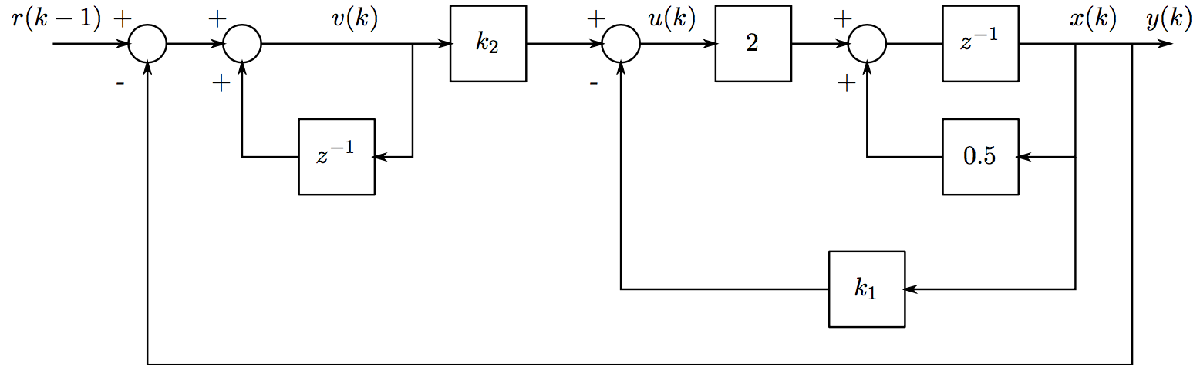

The sample period for the loop is $T=0.1 \mathrm{s}$. Clearly, $k_1$ is the integral gain and $k_2$ is the proportional gain.

**Problem 1**  Write down the state equations of the system, including the inputs and states. Show that the state equations of the system are:


$$\left[\matrix{ x(k+1) \cr v(k+1)}\right] = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{ x(k) \cr v(k) }\right] + \left[\matrix{ 2 \cr -2}\right]u(k) + \left[\matrix{ 0 \cr 1 }\right] r(k)$$


**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.



**Problem 2**  Write down the state equations for the system when $t\rightarrow \infty$. The reference input is to be held constant.

**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.




**Problem 3**  Define the new incremental variables:


$$x_e(k) = x(k) - x(\infty) \\ v_e(k) = v(k) - v(\infty) \\ u_e(k) = u(k) - u(\infty)$$


Now write down the state equations of the system in terms of the new variables above. What is the new feedback law?

**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.




**Problem 4**  Design a optimal steady state controller for the system above such that the performance index:


$$J = \frac{1}{2}\sum\limits_{k=0}^\infty \left[\left[\matrix{ x_e(k) \cr v_e(k) }\right]^\text{T} \mathbf{R}_1 \left[\matrix{ x_e(k) \cr v_e(k) }\right] + u_e^\text{T}(k) \mathbf{R}_2 u_e(k)\right]$$


is minimized where:


$$\mathbf{R}_1 = \left[\matrix{100 & 0 \cr 0 & 1}\right], \qquad \mathbf{R_2}=1$$


Find the optimal feedback gain matrix for the servo system.

**Solution:**

% Your solution goes here:




**Problem 5**  Simulate the servo control system response to a step change in the reference input. Plot the input to the system on one plot and in two different plots below, the output of the integrator $v(k)$ and the system output $y(k)$. Explain your results.

**Solution:**

% Your solution goes here:



